# IIR filters

**Realising IIR filters**

clear all; clc;

%filter requirements
fs = 500;

M = 454; %order of the previous filter
M_notch = 6; %order of the previous notch filter
fcLow = 125; %125Hz
fcHigh = 5; %5Hz
fcComb = 50; %50Hz
qComb = 35; %Q factor
bwComb = (fcComb/(fs/2))/qComb;

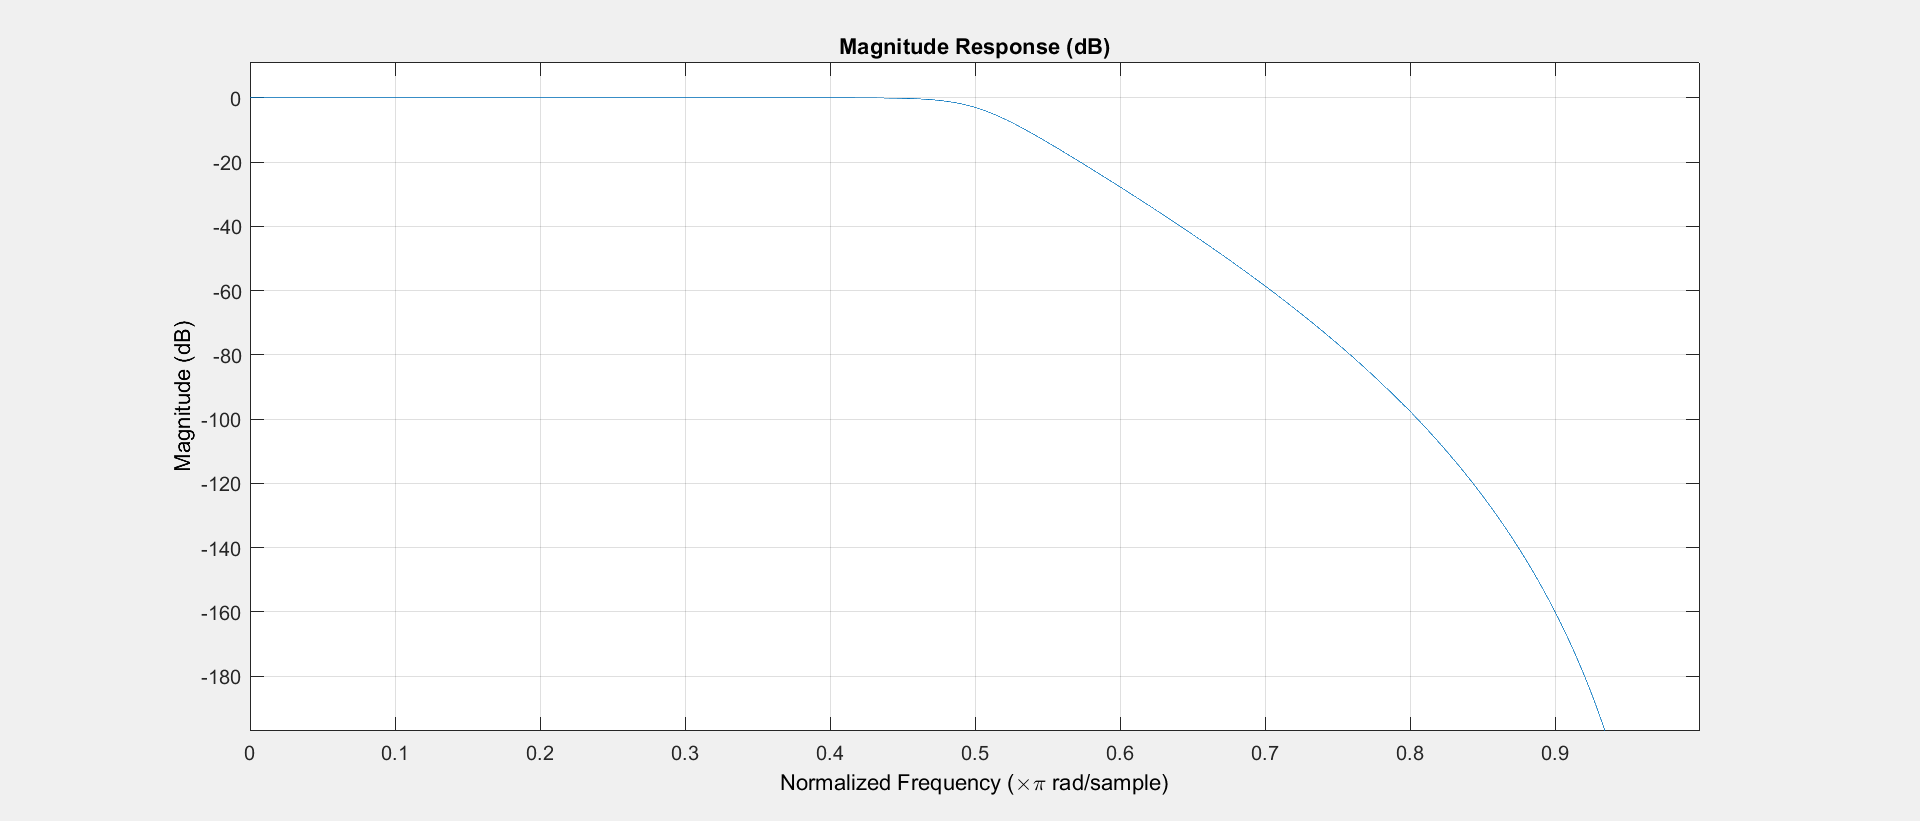

%the higher order cases to unsatbailty IIR filteres .
%Realising IIR HP ,IIR HP , comb filters using M as 10
M = 10;

%LPF M = 10
[coff_n_low,coff_d_low] = butter(M , (2* fcLow) /fs , 'low');
fvtool(coff_n_low,coff_d_low);

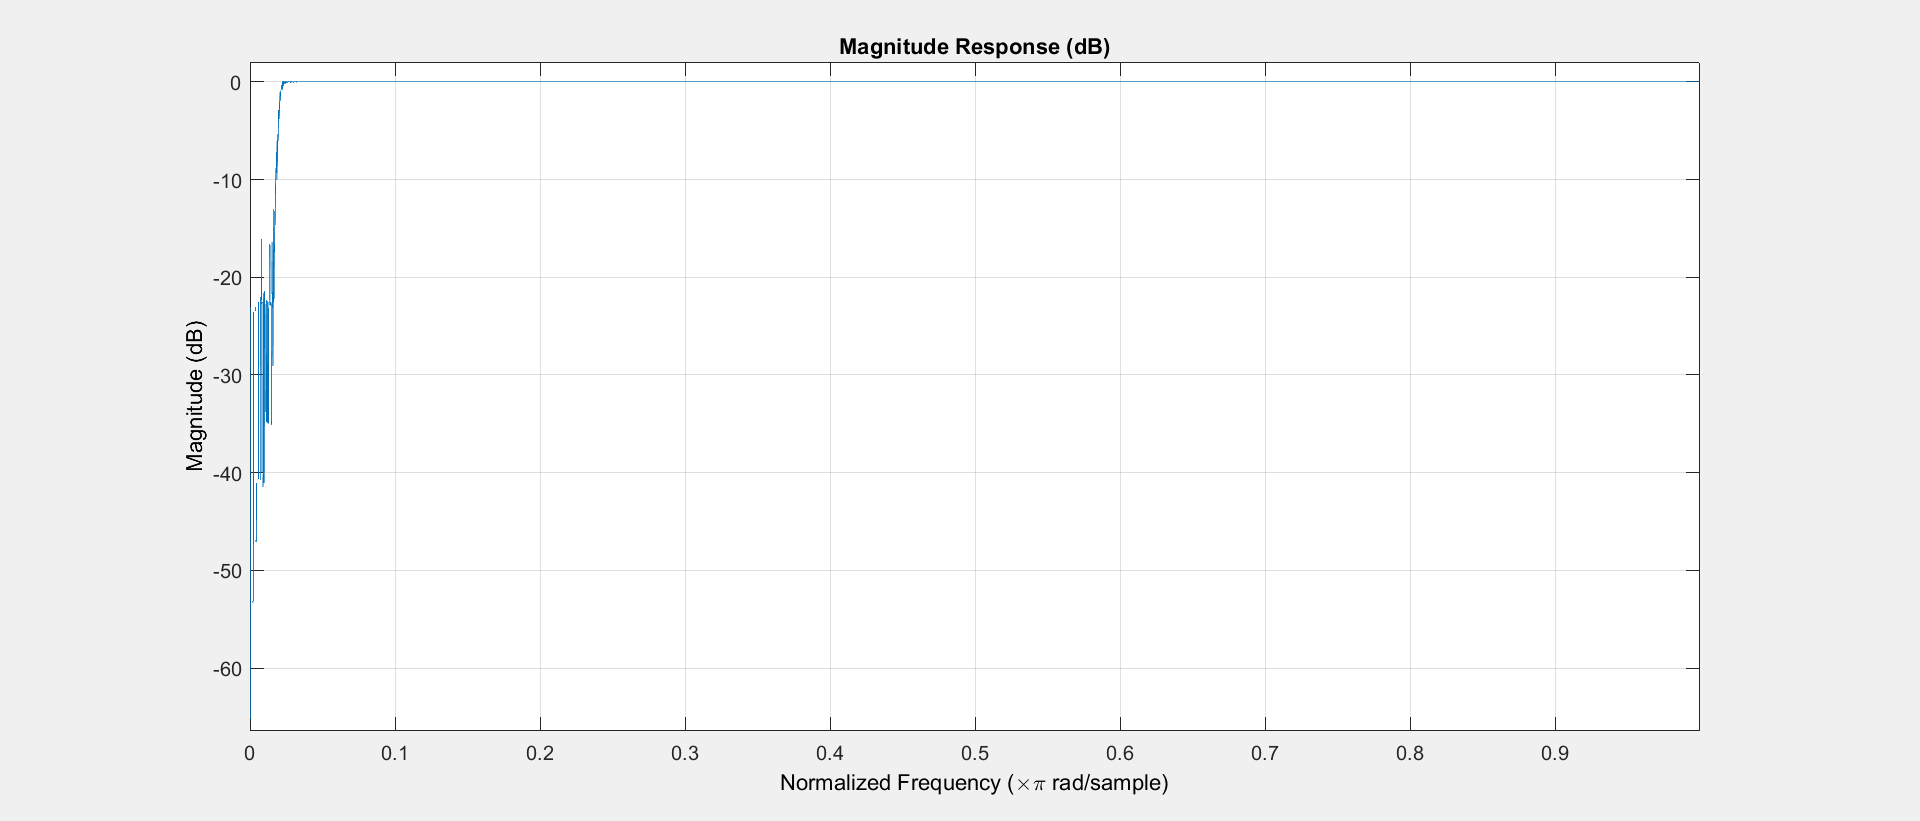


%HPF M = 10
[coff_n_high,coff_d_high] = butter(M , (2* fcHigh) /fs , 'high');
fvtool(coff_n_high,coff_d_high);

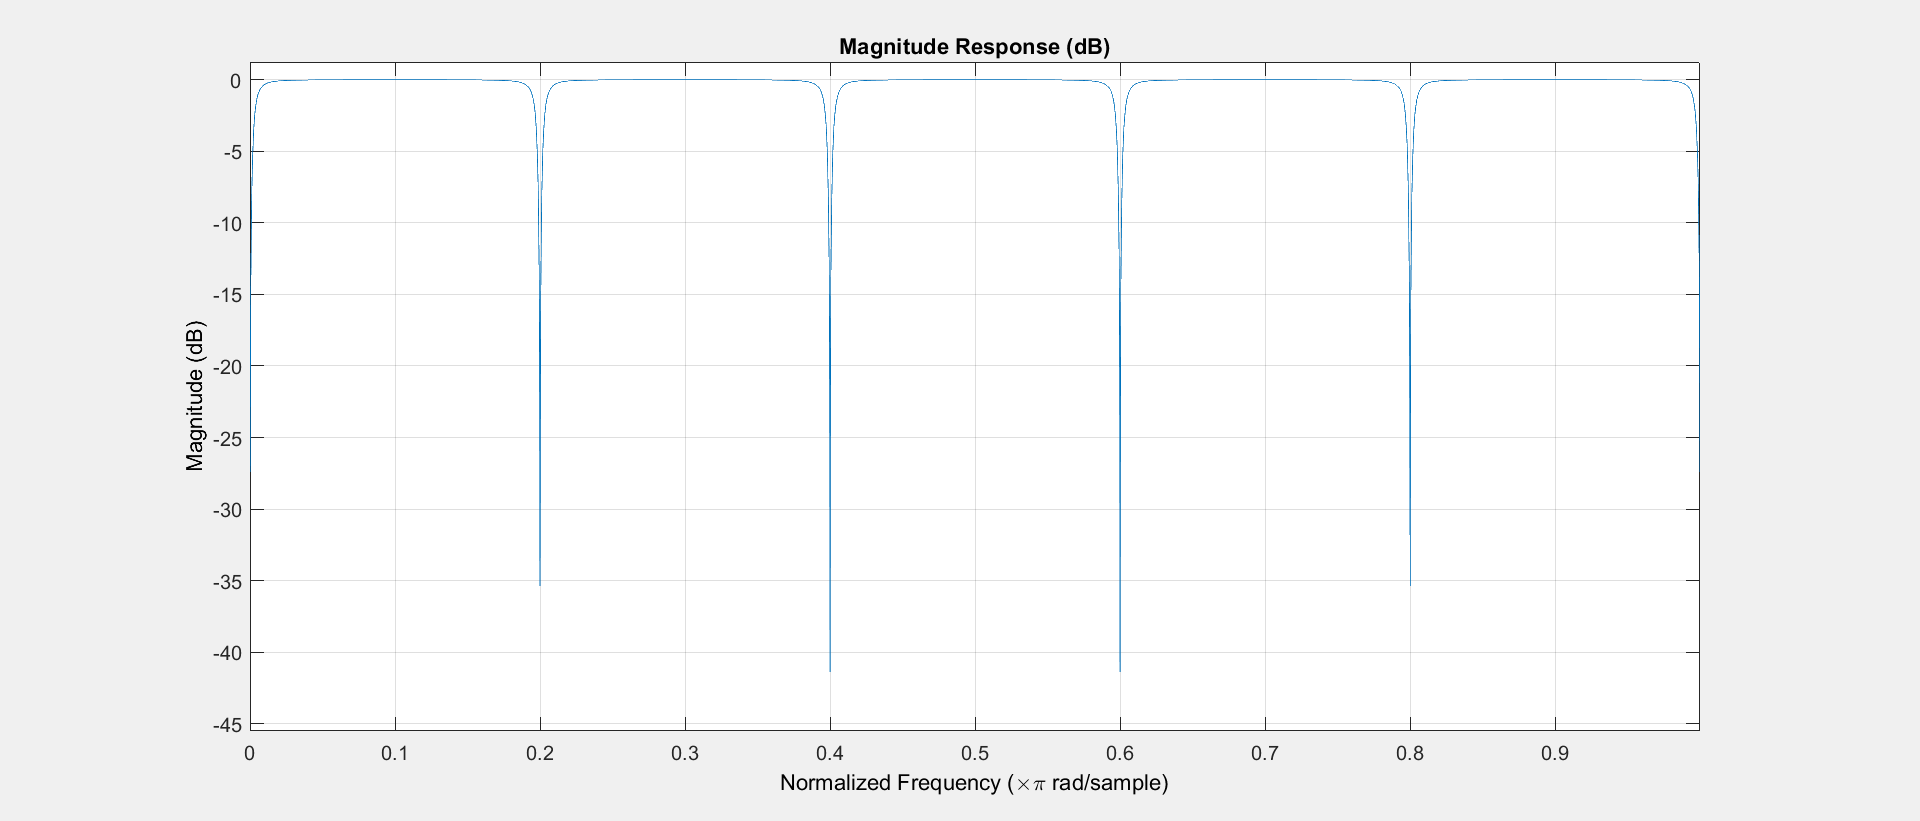

%comb M = 10
[coff_n_comb,coff_d_comb]=iircomb(fs/fcComb,bwComb ,'notch');
fvtool(coff_n_comb,coff_d_comb);

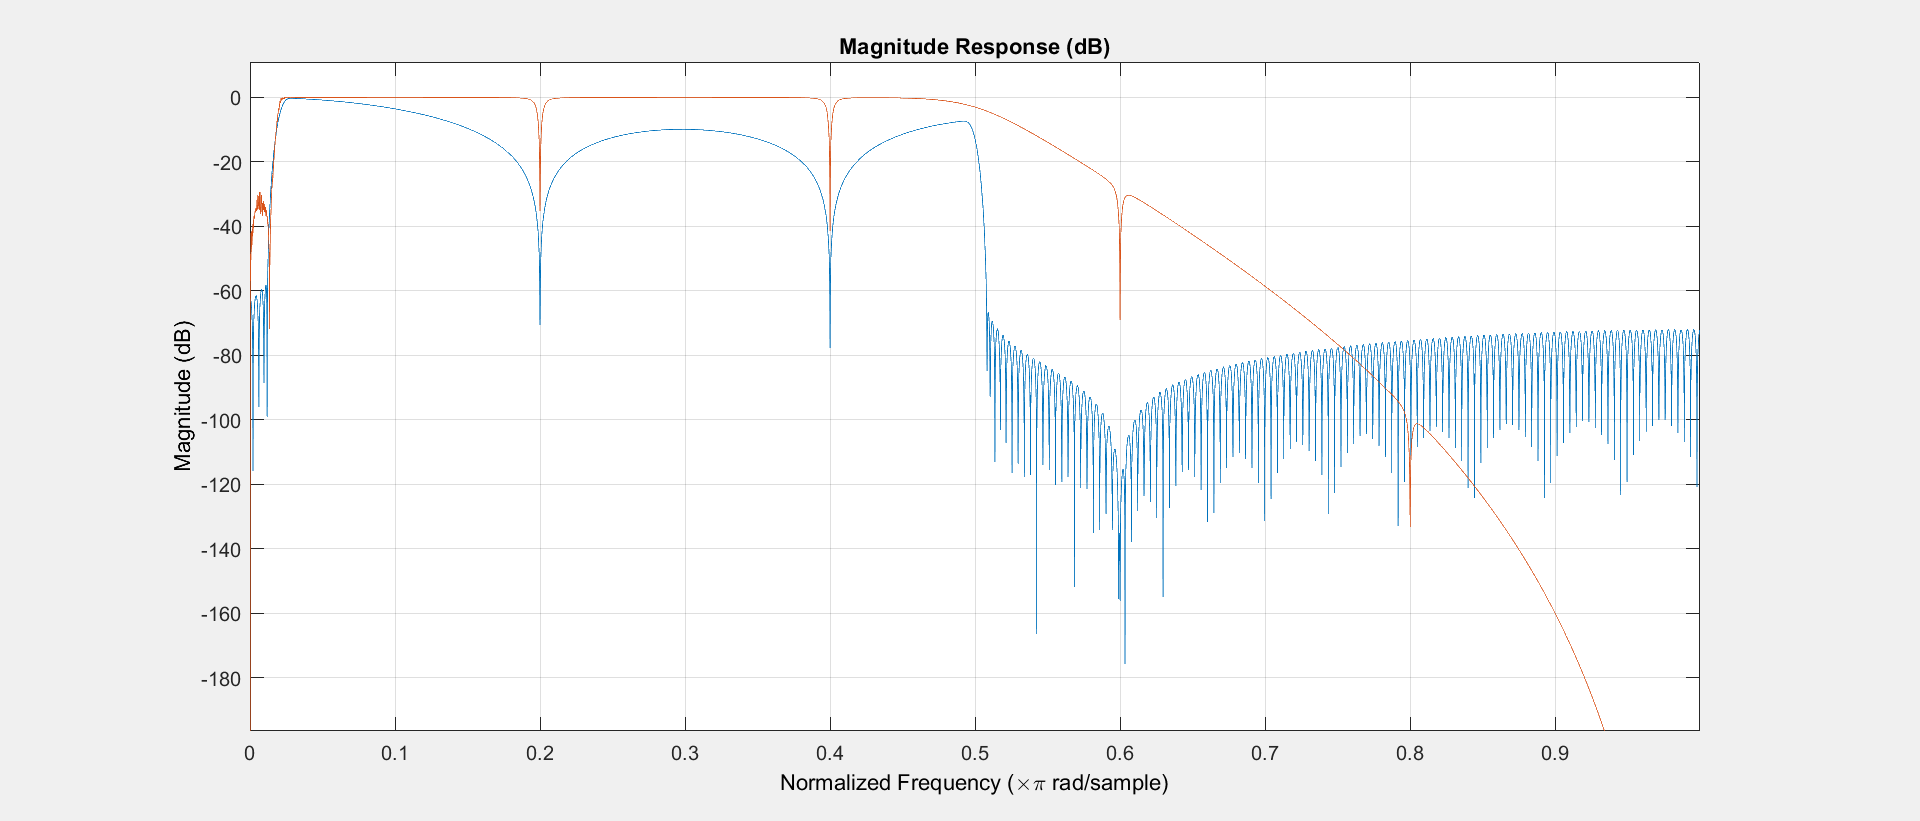

coff_n_mix = conv(conv(coff_n_low , coff_n_high) , coff_n_comb);
coff_d_mix = conv(conv(coff_d_low , coff_d_high) , coff_d_comb);

%load FIR filter coefficents
load FIR_coefficents.mat ;
fvtool(cascade,1 ,coff_n_mix,coff_d_mix);


load ECG_with_noise.mat;
x = 1 : length(nECG);  %X axis
t = x / fs; %scaled X axis according to fs to obtain real time axis

**Filtering methods using IIR filters**

%forward
 LP_ECG_f = filter(coff_n_low,coff_d_low,nECG);
 HP_LP_ECG_f = filter(coff_n_high,coff_d_high,LP_ECG_f);
 HP_LP_comb_ECG_f = filter(coff_n_comb,coff_d_comb,HP_LP_ECG_f);


%plot nECG signal
fig = figure;
subplot(4,1,1)
plot(t, nECG,'black');  %plotn ECG signal
title('noisy ECG signal(Forward)');
xlim([10,12]);

%plot LPF forward filtered signal
subplot(4,1,2)
plot(t, LP_ECG_f,'g');  %plot Low passed ECG signal
title('LPF applied ECG signal(Forward)');
xlim([10,12]);


%plot LPF + HPF forward filtered signal
subplot(4,1,3)
plot(t, HP_LP_ECG_f,'b');  %plot low passed and high passed ECG signal
title('LPF + HPF applied ECG signal(Forward)');
xlim([10,12]);


%plot LPF + HPF +Comb forward filtered signal
subplot(4,1,4)
plot(t, HP_LP_comb_ECG_f,'r');  %plot low passed , high passed and notch filtered ECG signal
title('LPF + HPF + Comb applied ECG signal(Forward)');
xlim([10,12]);

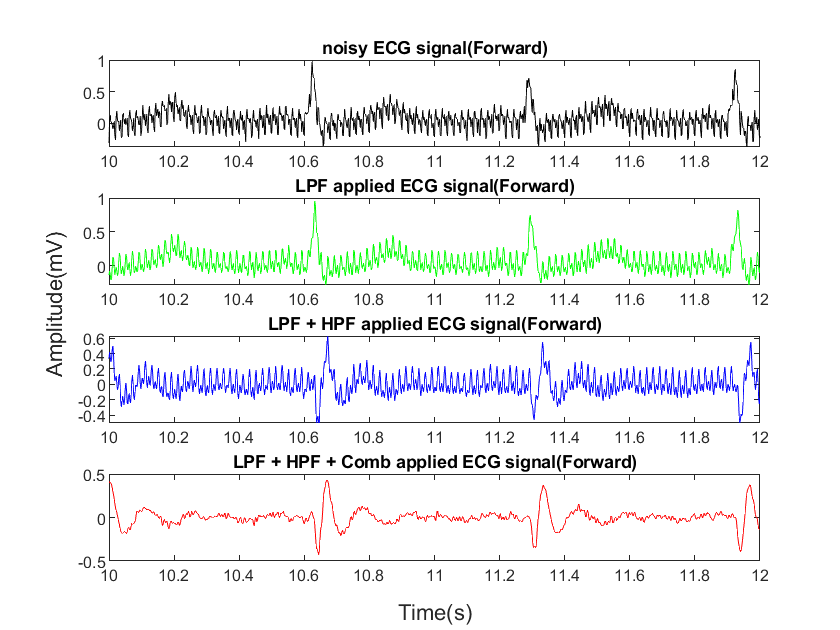

%figure confgiurations
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Amplitude(mV)');
xlabel(han,'Time(s)');

%forward+backward
 LP_ECG_fb = filtfilt(coff_n_low,coff_d_low,nECG);
 HP_LP_ECG_fb = filtfilt(coff_n_high,coff_d_high,LP_ECG_fb);
 HP_LP_comb_ECG_fb = filtfilt(coff_n_comb,coff_d_comb,HP_LP_ECG_fb);
 

%plot nECG signal
fig = figure;
subplot(4,1,1)
plot(t, nECG,'black');  %plotn ECG signal
title('noisy ECG signal(Forward-Backward)');
xlim([10,12]);


%plot LPF forward + backward filtered signal
subplot(4,1,2)
plot(t, LP_ECG_fb,'g');  %plot Low passed ECG signal
title('LPF applied ECG signal(Forward-Backward)');
xlim([10,12]);

%plot LPF + HPF  forward + backward filtered signal
subplot(4,1,3)
plot(t, HP_LP_ECG_fb,'b');  %plot low passed and high passed ECG signal
title('LPF + HPF applied ECG signal(Forward-Backward)');
xlim([10,12]);

%plot LPF + HPF + Comb  forward + backward filtered signal
subplot(4,1,4)
plot(t, HP_LP_comb_ECG_fb,'r');  %plot low passed , high passed and notch filtered ECG signal
title('LPF + HPF + Comb applied ECG signal(Forward-Backward)');
xlim([10,12]);

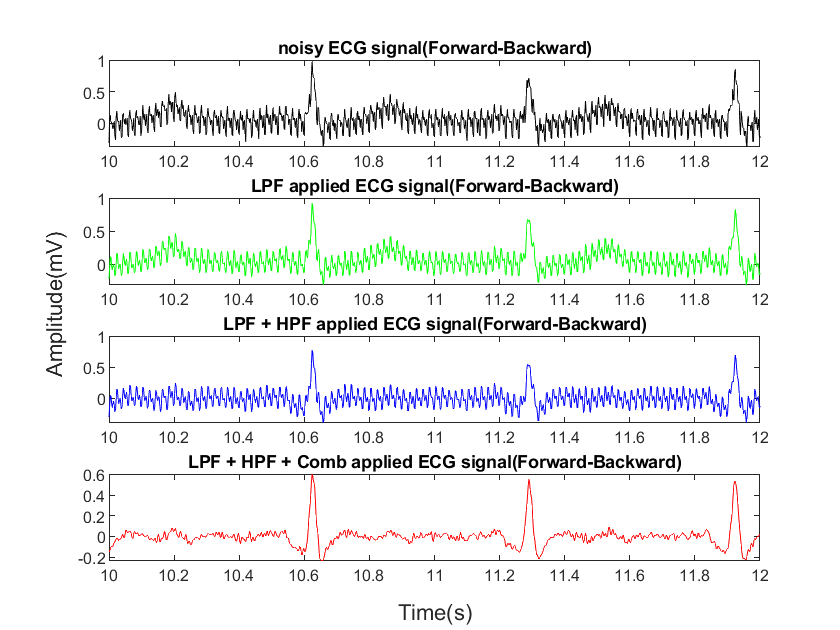

%plot configs
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Amplitude(mV)');
xlabel(han,'Time(s)');

%%apply fir filter to signal
fir_output = filter(cascade , 1 , nECG);
%compansate delay
gd_fir = round(grpdelay(cascade,1 ,1));
t_fir = t  - gd_fir/fs;

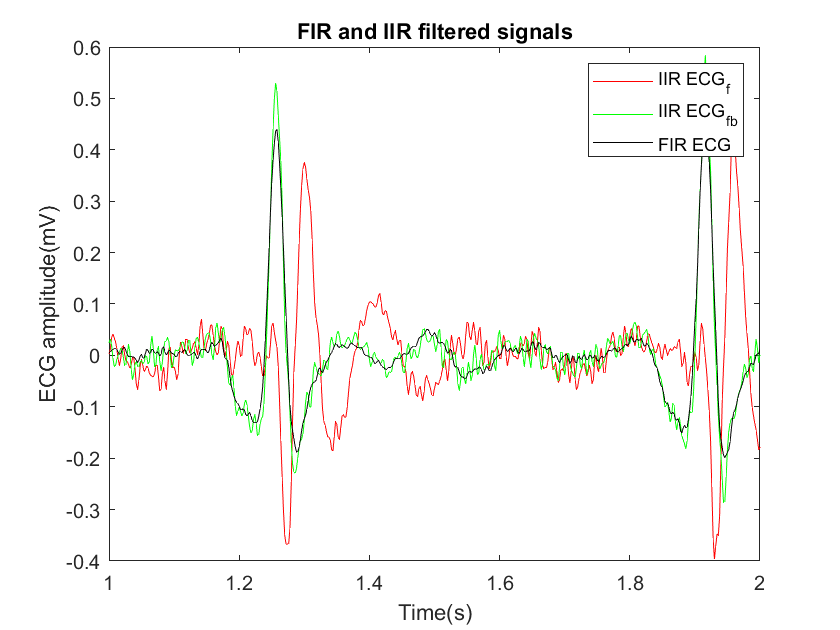

%=plot FIR and IIR outputs
%plot time domain output
figure;
plot( t,HP_LP_comb_ECG_f,'r',t,HP_LP_comb_ECG_fb,'g',t_fir,fir_output,'black');  %plot ECG signal
xlim([1,2]);
xlabel('Time(s)');
ylabel('ECG amplitude(mV)');
title('FIR and IIR filtered signals');
legend('IIR ECG_f' , 'IIR ECG_f_b' , 'FIR ECG');

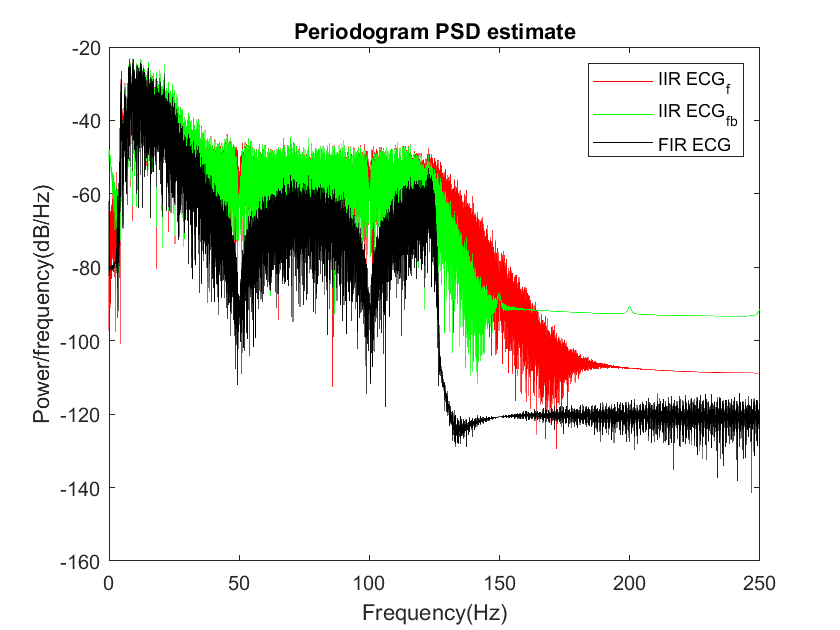


% %Plot the power spectral density (PSD) estimat
[pxx1,w1] = periodogram(HP_LP_comb_ECG_f,[],length(HP_LP_comb_ECG_f),fs);
[pxx2,w2] = periodogram(HP_LP_comb_ECG_fb,[],length(HP_LP_comb_ECG_fb),fs);
[pxx3,w3] = periodogram(fir_output,[],length(fir_output),fs);
figure;
plot(w1,10*log10(pxx1) , 'r',w2,10*log10(pxx2) , 'g',w3,10*log10(pxx3) , 'black' )
xlabel('Frequency(Hz)');
ylabel('Power/frequency(dB/Hz)');
title('Periodogram PSD estimate');
legend('IIR ECG_f' , 'IIR ECG_f_b' , 'FIR ECG');
hold off